# Homework 5 (Solutions)

Math 3607, Autumn 2021

Tae Eun Kim

## Problem 1 (Improved Triangular Substitutions)

**Note.** All functions written for this problem (`backsub`, `forelim`, and `ltinverse)` are all found at the very last section titled "Functions Used". This way, they can be called anywhere in the live script especially for the sake of testing. However, they are also included within my explanation as Code Examples for your convenience.

(a) The code provided in lecture can be easily improved to handle multiple triangular systems at once. 

### Backward Substitution (multiple systems)

The following version can handle $UX = B$ where $B \in \mathbb{R}^{n \times p}$, which demands $X \in \mathbb{R}^{n \times p}$ as well. Pay attention to how the added dimensions in $X$ and $B$ are handled in the code below. 

Note that the function can handle a single system $U\mathbf{x} = \mathbf{b}$ without any issue using the same syntax as the original version. So we can use it to fully replace the original version presented in class, hence no change in the function name. 

Note that we can vectorize the code by removing the outer loop and slightly modifying the single line inside the innermost loop. 

### Forward Elimination (multiple systems)

Similar modification is made below for forward elimination.

This can also be vectorized as shown for the backward substitution routine above.

(b) The full program `ltinverse` is listed at the end of the file. The key segment of the program is just one line

Note how directly the code translates the mathematical description of the problem of solving $LX = I$ to fine the inverse $X = L^{-1}$ using forward elimination. One more to note is that `eye(size(L))` generates the identity matrix that is of the same size as $L$, which reads very naturally. 

**Testing 1.** Using $L_1$:

L1 = [2 0 0;
      8 -7 0;
      4 9 -27];
L1inv = [1/2 0 0;              % analytical inverse
         4/7 -1/7 0;
         50/189 -1/21 -1/27];  % numerical inverse
L1invNum = ltinverse(L1);

One could output `L1inv` and `L1invNum` and compare them entry by entry. Another way, which is almost always preferred, is to calculate the norm of the difference of the two matrices. A small norm means a small difference.

norm(L1inv - L1invNum)

ans =      0

Looking good!

**Testing 2.** We proceed in the same fashion as above, now using $L_2$.

L2 = [1 0 0 0;
      1/3 1 0 0;
      0 1/3 1 0;
      0 0 1/3 1];
L2inv = [1 0 0 0;
         -1/3 1 0 0;
         1/9 -1/3 1 0;
         -1/27 1/9 -1/3 1];
L2invNum = ltinverse(L2);
norm(L2inv - L2invNum)

ans =      0

Fantastic!

### Further Demonstration 

Here is an additional demonstration of testing your code. Unlike the previous ones, I will compare the code `ltinverse` against MATLAB's built-in solver. For this demo, I will use a $10\times 10$ lower triangular matrix created by

n = 10;
L = tril(magic(n))

L =     92     0     0     0     0     0     0     0     0     0
    98    80     0     0     0     0     0     0     0     0
     4    81    88     0     0     0     0     0     0     0
    85    87    19    21     0     0     0     0     0     0
    86    93    25     2     9     0     0     0     0     0
    17    24    76    83    90    42     0     0     0     0
    23     5    82    89    91    48    30     0     0     0
    79     6    13    95    97    29    31    38     0     0
    10    12    94    96    78    35    37    44    46     0
    11    18   100    77    84    36    43    50    27    59


#### Inspection of Residuals

We can find its inverse by asking MATLAB to solve $LX = I$ using the backslash, which is essentially what happens when `inv` is called.

Linv = L\eye(n);   % or Linv = inv(L);

**Big Question.** We do not know the true inverse. How can we check the computed result?

Since we do not know the true analytic inverse, we cannot calculate the (*forward*) error associated with `Linv, `and so it is hard to say whether the result is good or bad. However, if MATLAB did a good job, then it must be the case that `L*Linv` is very close to the identity. In other words, `L*Linv - eye(n)` must be really close to the zero matrix. This difference $LX - I$ of the two sides is called the *residual *and it is an example of *backward *error; see Section 1.3 of **FNC** for more information.

norm(L*Linv-eye(n))

ans =       1.99225401607197e-15

The norm of the residual is at the level of machine epsilon. 

Likewise, let's calculate the inverse using our code and compute the norm of the residual:

myLinv = ltinverse(L);
norm(L*myLinv - eye(n))

ans =       3.00841133167772e-15

This looks good as well.

As seen above, 

*Residuals provide one way of checking the computation when the true answer is unknown.* 

Lastly, let's see how the two results compare:

norm(Linv - myLinv)

ans =       7.90892925731122e-17

The two results show a very good agreement. If one is certain that one of the two is highly accurate, then this confirms that the other is also an accurate computation of the inverse. 

## Problem 2 (Triangular substitutions and stability)

(a) This is a simple linear algebra exercise. Omitted.

(b) 

alpha = 0.1;
b = [alpha 0 0 0 1]';
for beta = 10.^(1:12)
    A = [1 -1 0 alpha-beta beta;
        0 1 -1 0 0;
        0 0 1 -1 0;
        0 0 0 1 -1;
        0 0 0 0 1];
    x_backsub = backsub(A,b);
    x = A\b;
    if beta == 10
        fprintf('%5s %12s %12s\n', 'beta', 'backsub', 'backslash')
        fprintf('%s\n', repmat('-',1,31))
    end
    fprintf('%5.0e %12.2e %12.2e\n', beta, abs(x_backsub(1)-1), abs(x(1)-1))
end

 beta      backsub    backslash


-------------------------------


1e+01     4.44e-16     0.00e+00
1e+02     5.77e-15     0.00e+00
1e+03     2.28e-14     0.00e+00
1e+04     3.64e-13     0.00e+00
1e+05     5.82e-12     0.00e+00
1e+06     2.33e-11     0.00e+00
1e+07     3.73e-10     0.00e+00
1e+08     5.96e-09     0.00e+00
1e+09     2.38e-08     0.00e+00
1e+10     3.81e-07     0.00e+00
1e+11     6.10e-06     0.00e+00
1e+12     2.44e-05     0.00e+00


The solution obtained using `backsub` gets deteriorated as $\beta$ increases. This is due to the fact that $\alpha - \beta \approx -\beta$ for large $\beta$ (while $\alpha$ is fixed), which gives rise to catastrophic cancellation in the process of backward substitution. MATLAB's built-in backslash operator avoids this numerical instability by pivoting; it calculates the solution accurately.

## Problem 3 (Vectorizing `mylu.m`)

(a) Following the instruction of the problem, the body of the function is changed to

(b)

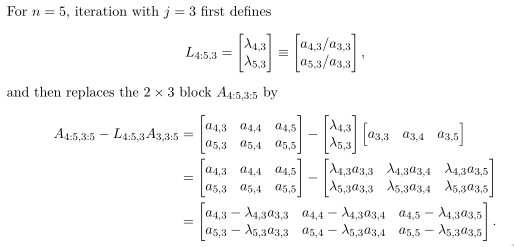

## Problem 4 (Application of LU factorization: determinant)

(a) Recall from linear algebra that $\det(LU) = \det(L) \det(U)$. In addition, recall that the determinant of a triangular matrix is the product of its diagonal entries. Since $L$ in the LU factorization is a unit lower triangular matrix, it follows that

$\det(A) = \det(LU) = \det(L) \det(U) = (1 \cdot 1 \cdots 1)(u_{11} u_{22} \cdots u_{nn}) = u_{11} u_{22} \cdots u_{nn}$.

(b) The previous part suggests that we can write the following program computing the determinant of a given matrix:

Since $L$ is not needed in the computation, the LU factorization routine is called with  `[~,U] = mylu(A)`. Let's test it.

for n = 3:7
    A = magic(n);
    myDet = determinant(A);
    Det = det(A);
    if n == 3     % print header
        fprintf(' %2s %20s %20s %12s\n', 'n', 'myDet', 'Det', 'rel. error')
        fprintf(' %57s\n', repmat('-', 1, 57))
    end
    fprintf(' %2d %20.8g %20.8g %12.4g\n', n, myDet, Det, abs((myDet-Det)/Det))   
end

  n                myDet                  Det   rel. error


 ---------------------------------------------------------


  3                 -360                 -360            0
  4         3.623768e-13       -1.4495072e-12         1.25
  5              5070000              5070000    7.348e-16
  6                    0       -8.0494971e-09            1
  7        -3.480528e+11        -3.480528e+11    3.507e-16


## Problem 5 (Proper usage of `lu`)

Recall that $A\mathbf{x} = \mathbf{b}$ is solved in MATLAB by `x=A\b`. In other words, the mathematical notation $\mathbf{x} = A^{-1}\mathbf{b}$ is equivalent to the MATLAB statement `x=A\b`. Thus, the MATLAB expression `x=U\L\b`, which is equivalent to `x=(U\L)\b`,  calculates $\mathbf{x} = (U^{-1}L)^{-1}\mathbf{b} = L^{-1} U\mathbf{b}$. This is different from the correct solution $\mathbf{x} = U^{-1}L^{-1}\mathbf{b}$.

Below is a short demo:

A = rand(5);
b = rand(5,1);
[L,U] = mylu(A);
x = U\(L\b);
x_incorrect = U\L\b;
norm(A*x - b)

ans =        4.9063819216287e-15

norm(A*x_incorrect - b)

ans =           44.7950042806626

## Problem 6 (LM 10.1--12a,b,d)

All vectors appearing are in $\mathbb{R}^n$; all matrices are in $\mathbb{R}^{n \times n}$.

(a) We calculate $\mathbf{x} = ABCD\mathbf{b}$ as below

What MATLAB does is:

- form a vector `D*b`: $\sim 2n^2$ flops

- left-multiply the previous result by `C`: $\sim 2n^2$ flops

- left-multiply the previous result by `B`: $\sim 2n^2$ flops

- left-mulitply the previous result by `A`: $\sim 2n^2$ flops

In total, it takes $\sim 8n^2$ flops to calculate `x`. 

If it were to be computed by, say, 

the computation of `C*D` itself takes $\sim 2n^3$ flops already. 

**Lesson.** Try to avoid (matrix) $\times$ (matrix) multiplication if possible!

(b) To compute $\mathbf{x} = BA^{-1}\mathbf{b}$ efficiently, do

This way:

- calculate $A^{-1}\mathbf{b}$ using backslash operator `A\b`: $\sim \frac{2}{3}n^3$ flops (because `\` does a pivoted GE in general) 

- left-multiply the previous result by `B`: $\sim 2n^2$ flops (since it is a (matrix) $\times$ (vector) multiplication.)

So, all in all, it take $\sim \frac{2}{3} n^3$ flops. (Recall that we only retain the dominant term in the asymptotic notation.)

(d) To efficiently compute $\mathbf{x} = B^{-1} (C+A) \mathbf{b}$, do

By doing this:

- form `C + A`: $\sim n^2$ flops

- multiply it by `b`: $\sim 2n^2$ flops

- left-"divide" by `B `using `\ `(pivoted GE): $\sim \frac{2}{3}n^3$ flops 

Altogether, it takes $\sim \frac{2}{3} n^3$ flops. 

## Problem 7 (Matrix norms)

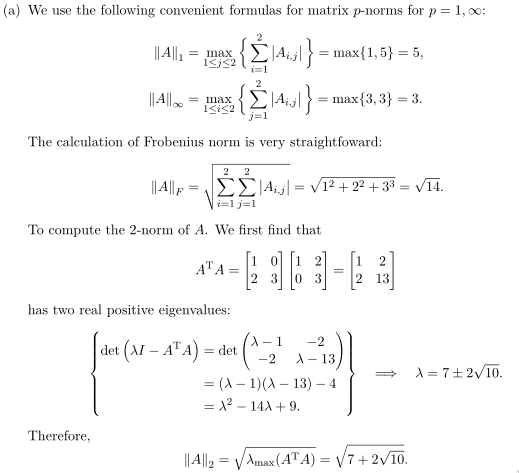

(b) 

Let's test the code.

A = [1 2; 0 3];

MatrixNorm(A, 1)

ans =      5

Agrees with the calculation.

MatrixNorm(A, 'inf')

ans =      3

Agreed.

MatrixNorm(A, 2)

ans =           3.65028153987288

sqrt(7+2*sqrt(10))

ans =           3.65028153987288

Agreed.

MatrixNorm(A, 'fro')

ans =           3.74165738677394

sqrt(14)

ans =           3.74165738677394

Agree!

## Functions Used

### Backward Substitutions

function X = backsub(U,B)
% BACKSUB X = backsub(U,B)
% Solve multiple upper triangular linear systems.
% Input:
%   U    upper triangular square matrix (n by n)
%   B    right-hand side vectors concatenated into an (n by p) matrix
% Output:
%   X    solution of UX=B (n by p)
    [n,p] = size(B);
    X = zeros(n,p); % preallocate
    for j = 1:p
        for i = n:-1:1
            X(i,j) = ( B(i,j) - U(i,i+1:n)*X(i+1:n,j) ) / U(i,i);
        end
    end
end

### Forward Elimination

function X = forelim(L,B)
% FORELIM X = forelim(L,B)
% Solve multiple lower triangular linear systems.
% Input:
%   L    lower triangular square matrix (n by n)
%   B    right-hand side vectors concatenated into an (n by p) matrix
% Output:
%   X    solution of LX=B (n by p)
    [n,p] = size(B);
    X = zeros(n,p); % preallocate
    for j = 1:p
        for i = 1:n
            X(i,j) = ( B(i,j) - L(i,1:i-1)*X(1:i-1,j) ) / L(i,i);
        end
    end
end

### Inverse of a lower triangular matrix

function X = ltinverse(L)
% LTINVERSE X = ltinverse(L)
% Find the inverse of a lower triangular matrix. 
% Input:
%   L    lower triangular square matrix (n by n)
% Output:
%   X    inverse of L, i.e., LX = I. (n by n)
    if ~istril(L) || diff(size(L))~=0 % if input is not lower triangular nor square
        error('The input must be a lower triangular square matrix');
    end
    X = forelim(L, eye(size(L)));
end

### Vectorized LU factorization

function [L,U] = mylu(A)
% MYLU   LU factorization (demo only--not stable!).
% Input:
%   A    square matrix
% Output:
%   L,U  unit lower triangular and upper triangular such that LU=A
    n = length(A);
    L = eye(n);   % ones on diagonal
    % Gaussian elimination
    for j = 1:n-1
        i = j+1:n;
        L(i,j) = A(i,j) / A(j,j);   % row multiplier
        A(i,j:n) = A(i,j:n) - L(i,j)*A(j,j:n);
    end
    U = triu(A);
end

### Determinant based on LU factorization

function D = determinant(A)
% DETERMINANT D = determinant(A)
% Calculate the determinant of A using LU factorization.
% Input:
%   A   square matrix
% Output:
%   D   determinant of A
% Dependency: mylu (see below)
    [~,U] = mylu(A);
    D = prod(diag(U));
end

### Matrix norm

function y = MatrixNorm(A, j)
% mat_norm   computes matrix norms
% Usage:
%   MatrixNorm(A, 1) returns the 1-norm of A
%   MatrixNorm(A, 2) is the same as mat_norm(A)
%   MatrixNorm(A, 'inf') returns the infinity-norm of A
%   MatrixNorm(A, 'fro') returns the Frobenius norm of A
    if j == 1
        y = max(sum(abs(A), 1));
    elseif j == 2
        y = sqrt(max(eig(A'*A)));
    elseif strcmp(j, 'inf')
        y = max(sum(abs(A), 2));
    elseif strcmp(j, 'fro')
        y = sqrt(sum(sum(abs(A).^2)));
    else
        error('Invalid second input.');
    end
end